# **SISTEMAS DE CONTROL **

# 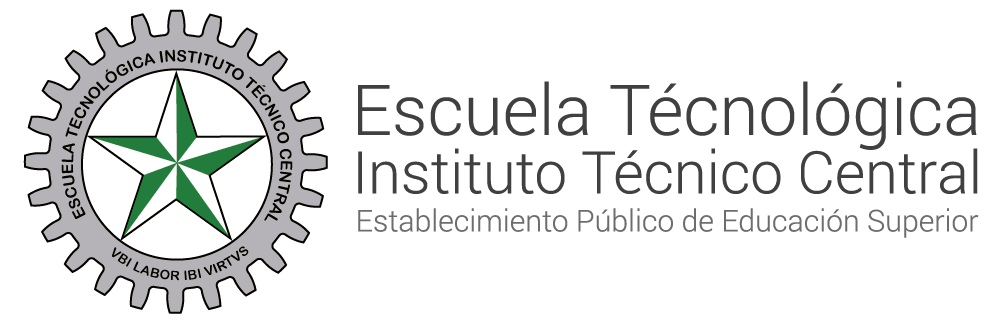

# **Sistemas de segundo órden**

#### Autor ING. JHEYSON FABIAN VILLAVISAN BUITRAGO 

**OBJETIVO** Comprender los sistemas de primer y segundo orden en el dominio del tiempo discreto.

En el contexto de sistemas lineales e invariantes en el tiempo (LTI), que son fundamentales en la teoría de control, un sistema de segundo orden es un tipo de sistema dinámico o sistema físico que se caracteriza por tener dos polos complejos en su función de transferencia.La función de transferencia de un sistema de segundo orden en el dominio de la frecuencia (para sistemas continuos) o en el dominio Z (para sistemas discretos) tiene la forma general:

Para sistemas continuos:


$$G\left(z\right)=\frac{\mathrm{cz}+d}{z^2 +\mathrm{az}+b}$$


### Ejercicio

Para la siguiente función de transferencia de un sistema en lazo abierto con retroalimentación unitaria:

                           
$$G(s) = \frac {1}{s(s+0.5)}
$$
    

- Hallar la función de transferencia en el dominio Z para T_s=1s

- Dibuje el diagrama de bloques la función de transferencia en lazo cerrado.

### 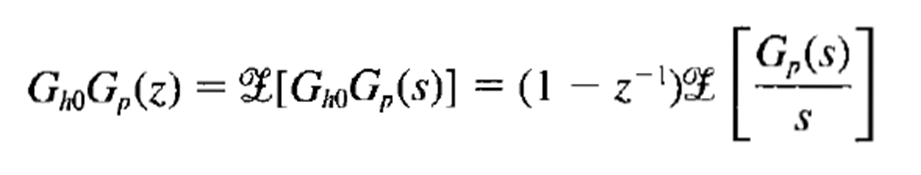

Usando la definición anterior para el sistema:


$$G(s) = \frac {1}{s(s+0.5)}
$$


Obtenemos la siguiente expresión

 
$$G[z]=(1-z^{-1}) Z (\frac{1}{s} *\frac {1}{s(s+0.5)}) 
$$
  

En donde definimos G_p como:


$$G_p=\frac{1}{s} *\frac {1}{s(s+0.5)}
$$


syms s
a=0.5;
numerador = [1];             
d_0 = [1 0];                    
d_1 = [1, a];
d_2 = [1 0];                    
d_3= conv(d_0, d_1);
denominador = conv(d_3, d_2);   
fprintf('*** Función de Transferencia en lazo abierto***\n');

*** Función de Transferencia en lazo abierto***


G_p = tf(numerador, denominador)


G_p =
 
        1
  -------------
  s^3 + 0.5 s^2
 
Continuous-time transfer function.
Model Properties


Ahora realizando expanción por funciones parciales se obtiene para G_p:


$$G_p=\frac{1}{s} *\frac {1}{s(s+0.5)}= \frac{2}{s^2}-\frac{4}{s}+\frac{4}{s+0.5}
$$


[r,p,k] = residue(numerador,denominador)

r =      4
    -4
     2


p =    -0.5000
         0
         0



k =

     []



Y_s_fract=(simplify(r(1)/(s-p(1)))+simplify(r(2)/(s-p(2)))+simplify(r(3)/(s^2-p(3))))

$$Y\_s\_fract = \frac{4}{s+\frac{1}{2}}-\frac{4}{s}+\frac{2}{s^{2}}$$

Realizando la transformada inversa de laplace, sabemos que:


$$G_p=\frac{1}{s} *\frac {1}{s(s+0.5)}= \frac{2}{s^2}-\frac{4}{s}+\frac{4}{s+0.5}
$$



$$\mathcal{L^{-1}} ({G_p})=\mathcal{L^{-1}} (\frac{2}{s^2}-\frac{4}{s}+\frac{4}{s+0.5})
$$



$${G_t}=2*kT-4+4e^{-k/2}
$$


syms k;
f = ilaplace(Y_s_fract, s, k)

$$f = 2\,k+4\,{\mathrm{e}}^{-\frac{k}{2}}-4$$

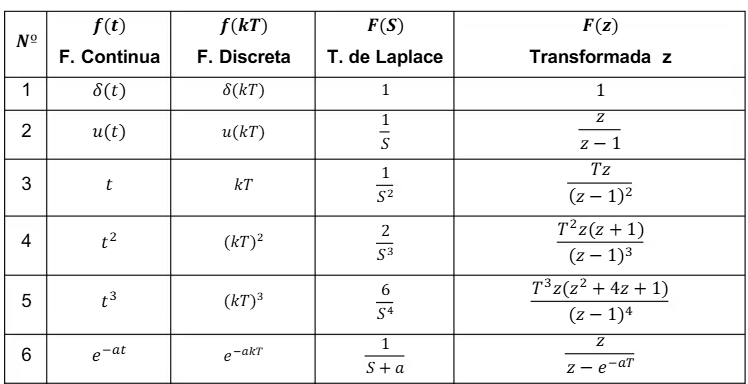

Ahora aplicando la transformada Z según la tabla obtenemos:


$$\frac{2\,z}{{{\left(z-1\right)}}^2 }+\frac{4\,z}{z-{\mathrm{e}}^{-\frac{1}{2}} }-\frac{4\,z}{z-1}$$


syms  T z 
F_z = ztrans(f, k, z)

$$F\_z = \frac{2\,z}{{\left(z-1\right)}^{2}}-\frac{4\,z}{z-1}+\frac{4\,z}{z-{\mathrm{e}}^{-\frac{1}{2}}}$$

Paso seguido, procedemos a multiplicar por el retenedor de orden cero: 


$$G[z]=(1-z^{-1}) Z (\frac{2*z}{z - 1)^2} - \frac{4*z}{z - 1} + \frac{4*z}{z - e^{-1/2}} )
$$


F_z_approx = vpa(collect((F_z)*(1-(1/z))), 3)

$$F\_z\_approx = \frac{0.703\,z+0.595}{1.65\,z^{2}-2.65\,z+1.0}$$

d_0 = [1 0];                    
d_1 = [1, a];
d_2 = [1 0];                    
denominador = conv(d_1, d_2);  
sys_z = c2d(tf(numerador, denominador), 1, 'zoh')


sys_z =
 
    0.4261 z + 0.3608
  ----------------------
  z^2 - 1.607 z + 0.6065
 
Sample time: 1 seconds
Discrete-time transfer function.
Model Properties


% Calcular la respuesta al escalón en el dominio Z
n = 0:1:40; % Vector de tiempo discreto
[y, n] = step(sys_z, n);
% Graficar la respuesta al escalón en el dominio Z
stem(n, y, 'b', 'filled');
xlabel('Muestras (n)');
ylabel('Respuesta al escalón');
title('Respuesta al escalón en el dominio Z');
grid on;
hold on
numerador = [1];             
d_0 = [1 0];                    
d_1 = [1, a];
denominador = conv(d_0, d_1);
G_s = tf(numerador, denominador)


G_s =
 
       1
  -----------
  s^2 + 0.5 s
 
Continuous-time transfer function.
Model Properties


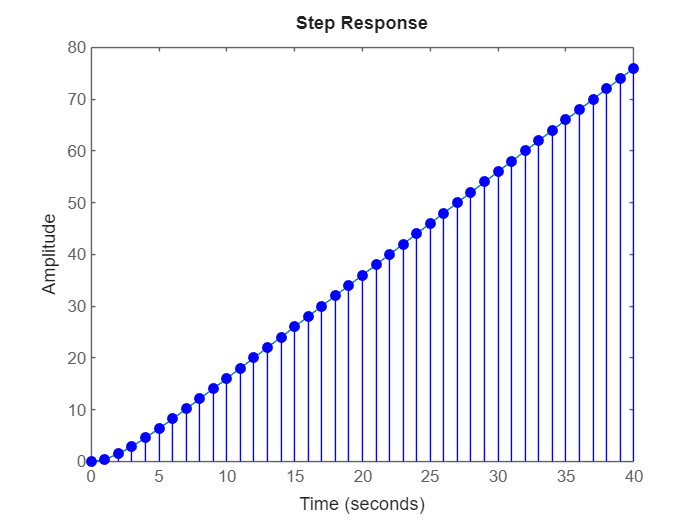

step(G_s)
xlim([0 40]);      
ylim([0 80]);     